#     Script # 3: Resource Allocation 

Written by Henk Wymeersch, (c) 2019, for the course Wireless Communications (SSY135), Chalmers University of Technology

## Statistical waterfilling

We consider an average power $\bar{P}$ and a target BER value. The SNR $\gamma$ has an exponential distribution. Note the difference between $p(\gamma)$ (the SNR density) and $P(\gamma)$ (the power allocation).

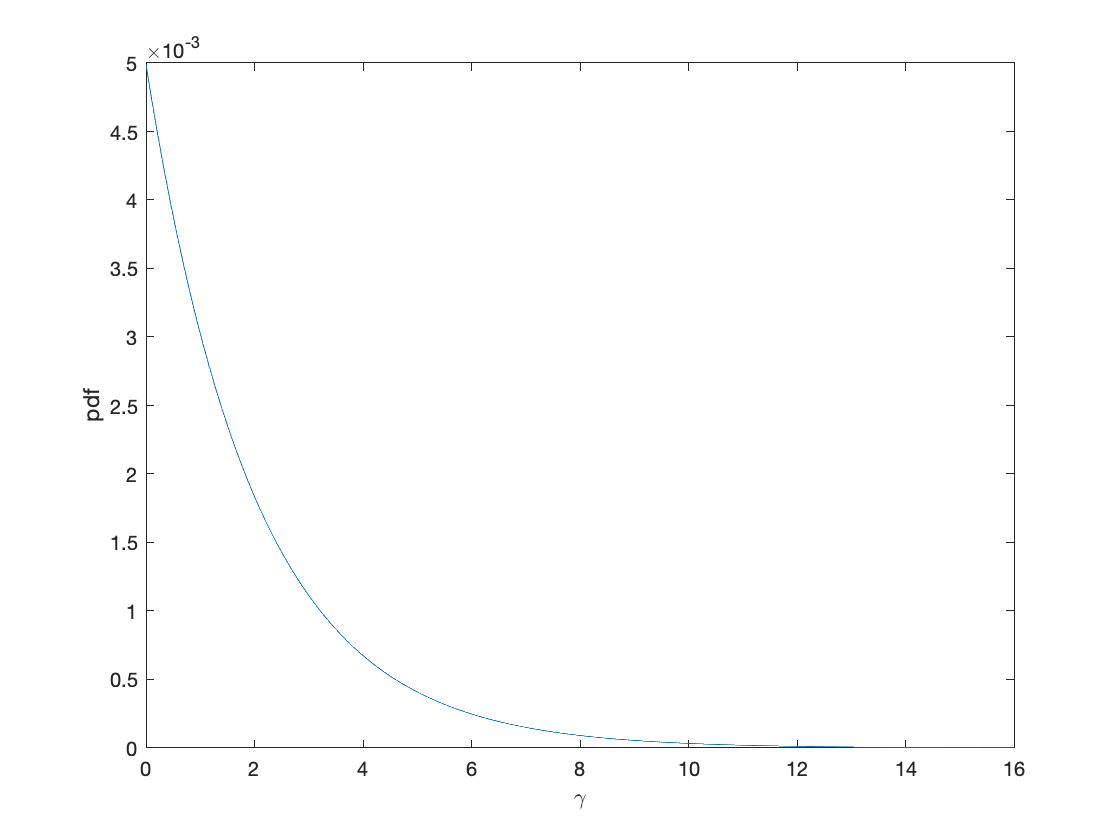

Pbar = 2;                % average power 
BER = 1e-3;              % target BER
K=-1.5/log(5*BER);
gamma=0:0.01:8*Pbar;         % range of SNRs
pgamma=exp(-gamma/Pbar)/Pbar;
pgamma=pgamma/sum(pgamma);
plot(gamma,pgamma);
xlabel('\gamma')
ylabel('pdf')

Now we run a [bisection method](https://en.wikipedia.org/wiki/Bisection_method) to find the waterlevel. We show the evolution of the average power as a function of the iteration index. 

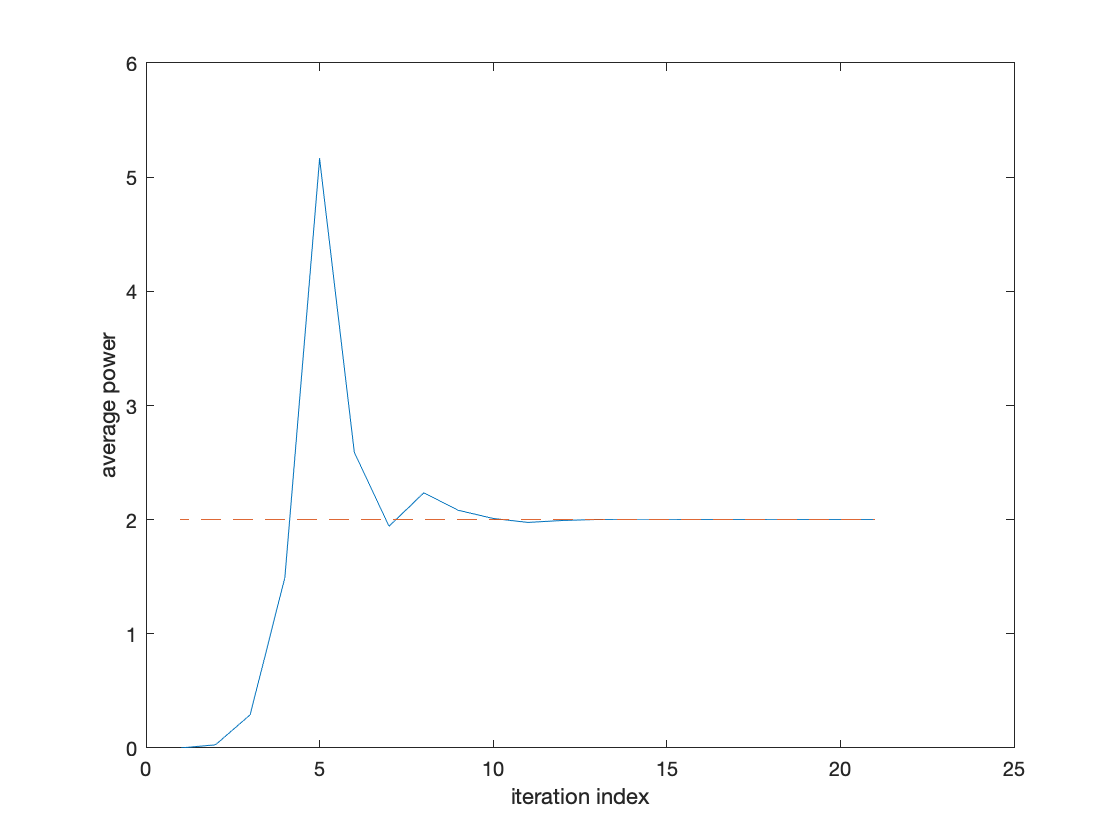

gammaKa=10*Pbar;             % max value
gammaKb=1e-10;              % min value
Pa=max(Pbar/K*(1/gammaKa-1./gamma),0);
Pavga=Pa*pgamma';
Pb=max(Pbar/K*(1/gammaKb-1./gamma),0);
Pavgb=Pb*pgamma';
Pvec=[];
ctr=0;
while (abs(gammaKa-gammaKb)>1e-5 && ctr <100)
    ctr=ctr+1;
    gammaKc=(gammaKa+gammaKb)/2;
    P=max(Pbar/K*(1/gammaKc-1./gamma),0);
    Pavg=P*pgamma';
    Pvec=[Pvec Pavg];
    if (Pavg>Pbar)
        gammaKb=gammaKc;
    else
        gammaKa=gammaKc;
    end
end
plot(1:ctr,Pvec,1:ctr,ones(1,ctr)*Pbar,'--')
xlabel('iteration index')
ylabel('average power')

The final allocation is now shown along expected rate. 

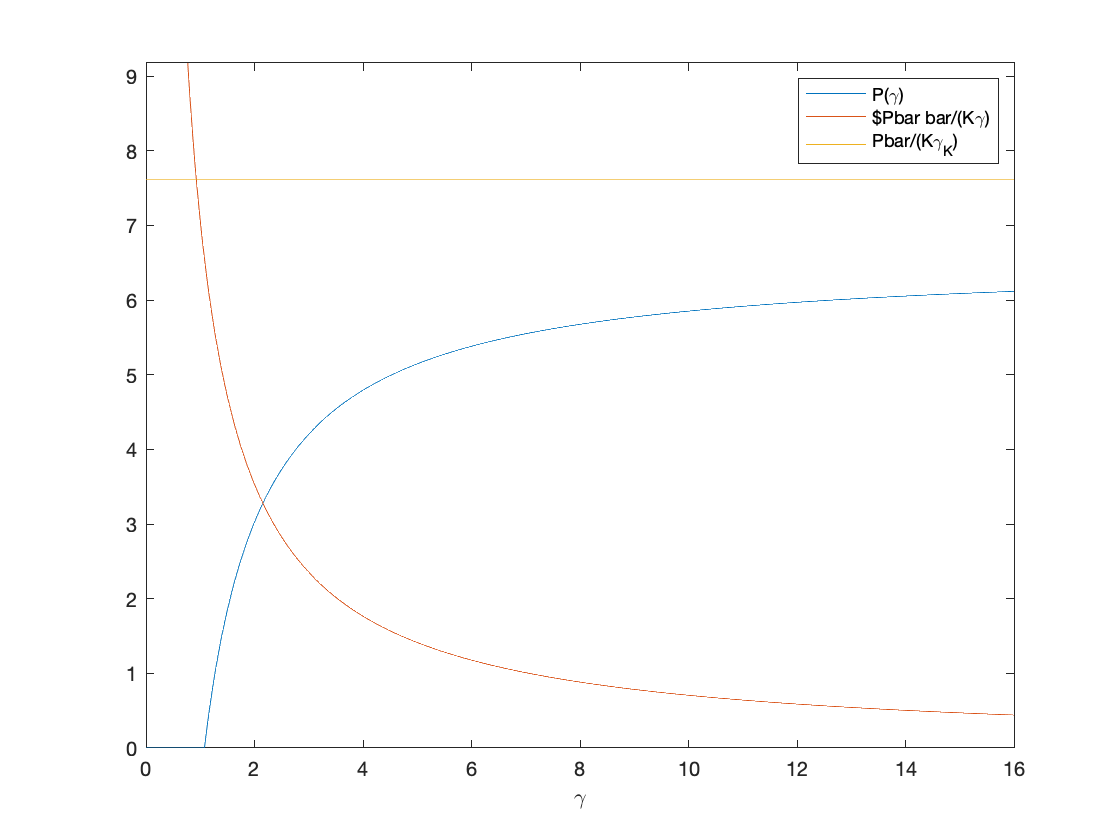

P=max(Pbar/K*(1/gammaKc-1./gamma),0);
plot(gamma,P,gamma,Pbar/K./gamma,gamma,Pbar/K*gammaKc*ones(size(gamma)));
legend('P(\gamma)','$Pbar bar/(K\gamma)','Pbar/(K\gamma_K)')
xlabel('\gamma')
axis([min(gamma) max(gamma) 0 1.5*max(P)])

ExpectedRate=log2(1+K*gamma.*P/Pbar)*pgamma' % bits per channel use

ExpectedRate = 0.7408

NominalRate = log2(1+K*gamma)*pgamma'        % using always the average power

NominalRate = 0.5708

You can compare this with the figure from the slides:

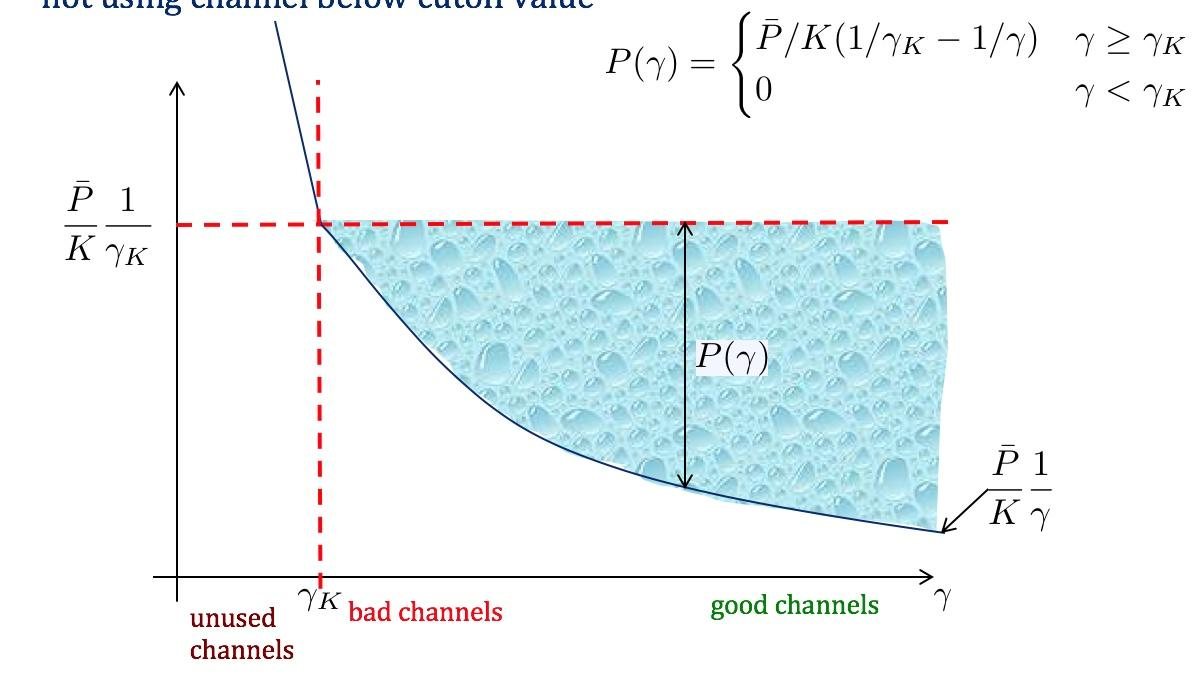

## Adaptive loading

Now we consider the case with $M$ deterministic channels. Now we will use $\bar{P}$ as a total power. We set $\gamma_{AL,i}=\alpha_i^2\bar{P}/(N_0B)$ for channel $i$. We again user the bisection method. 

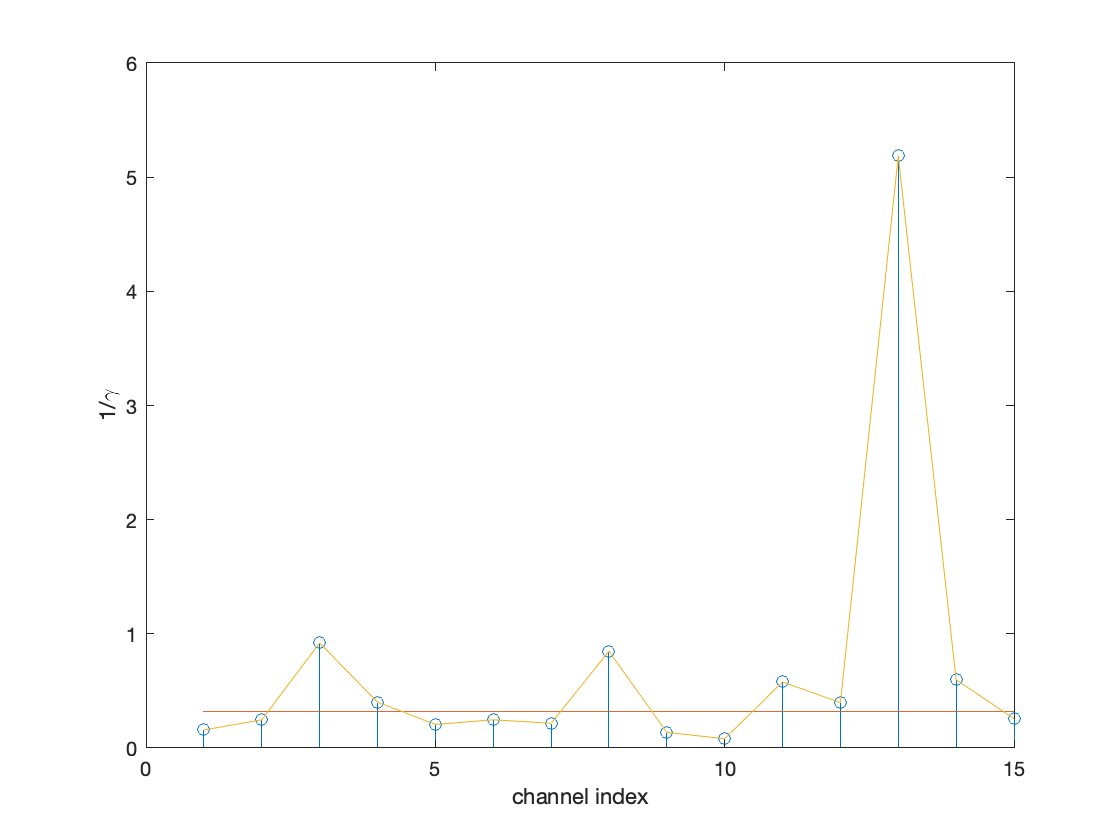

M=15;
gammaAL=Pbar*abs(randn(1,M)+1j*randn(1,M)).^2; % Rayleigh fading
a=10*max(gammaAL);              % max value
b=1e-10;                        % min value
Pa=max(Pbar*(1/a-1./gammaAL),0);
Ptota=sum(Pa);
Pb=max(Pbar*(1/b-1./gammaAL),0);
Ptotb=sum(Pb);
Pvec=[];
ctr=0;
while (abs(a-b)>1e-5 && ctr <100)
    ctr=ctr+1;
    c=(a+b)/2;
    P=max(Pbar*(1/c-1./gammaAL),0);
    Ptot=sum(P);
    Pvec=[Pvec Ptot];
    if (Ptot>Pbar)
        b=c;
    else
        a=c;
    end
end
stem(1:M,1./gammaAL);
hold on
plot(1:M,ones(1,M)/a,1:M,1./gammaAL)
xlabel('channel index')
ylabel('1/\gamma')

SumRate=sum(log2(1+gammaAL.*P/Pbar))   % sum-rate

SumRate = 6.4344

NominalRate =sum(log2(1+gammaAL/M))         % each channel gets power Pbar/M

NominalRate = 4.7403